% Clear workspace
clc;
clear;
close all;


% Define the DH transformation function (Standard DH Convention)
dh_transform = @(theta, d, a, alpha) [
    cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
    sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
    0,           sin(alpha),             cos(alpha),           d;
    0,           0,                      0,                    1];

L1 = 0.5;   % Height of the base
L2 = 1.3;   % First segment of the vertical arm
L3 = 1.6;   % Second segment of the vertical arm
L4 = 1;     % Third segment (fork)

% Joint angles (pose configuration in radians)
theta1 = 0;             % Base rotation
theta2 = 7/20 * pi;     % Lower the arm
theta3 = -5/6 * pi;     % Adjust to keep the fork horizontal
theta4 = 29/60 * pi;    % Fork rotation

% Create DH transformation matrices for each link
T1 = dh_transform(theta1, L1, 0, pi/2);  % Link 1
T2 = dh_transform(theta2, 0, L2, 0);     % Link 2
T3 = dh_transform(theta3, 0, L3, 0);     % Link 3
T4 = dh_transform(theta4, 0, L4, 0);     % Link 4

% Multiply the transformation matrices to get the full transformation
T_0_4_manual = T1 * T2 * T3 * T4;

% Display the manually calculated transformation matrix
disp('Manually calculated transformation matrix from base to end-effector:');

Manually calculated transformation matrix from base to end-effector:


disp(T_0_4_manual);

    1.0000    0.0000         0    1.6739
   -0.0000    0.0000   -1.0000   -0.0000
   -0.0000    1.0000    0.0000    0.0605
         0         0         0    1.0000





% Define the robot using DH parameters (4 DOF)
% Each Link represents a joint with its parameters: [theta d a alpha]
L(1) = Link([0 0.5 0 pi/2]);  % Base to Link 1
L(2) = Link([0 0 1.3 0]);     % Link 1 to Link 2
L(3) = Link([0 0 1.6 0]);     % Link 2 to Link 3
L(4) = Link([0 0 1 0]);       % Link 3 to End-Effector (Fork)

% Create the robot model
Robot = SerialLink(L, 'name', 'Forklift Robot');

% Forward Kinematics: Calculate end-effector pose using the toolbox
T_0_4_toolbox = Robot.fkine([theta1, theta2, theta3, theta4]);

% Display the toolbox-calculated transformation matrix
disp('Toolbox-calculated transformation matrix from base to end-effector:');

Toolbox-calculated transformation matrix from base to end-effector:


disp(T_0_4_toolbox);

             1   3.4e-16         0     1.674
    -2.082e-32 6.123e-17        -1-2.691e-17
      -3.4e-16         1 6.123e-17    0.0605
             0         0         0         1


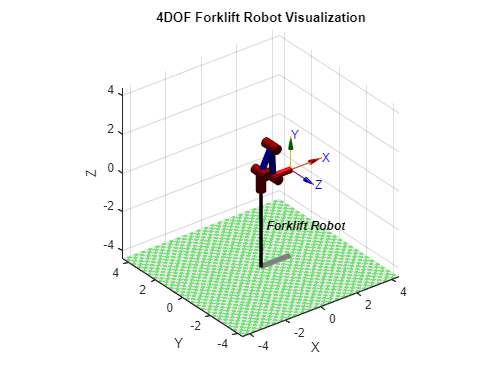


% Visualize the robot
figure;
Robot.plot([theta1, theta2, theta3, theta4]); % Plot the robot with given joint angles
title('4DOF Forklift Robot Visualization');